# **Cinemática Directa Manipulador 4R**

# **Felipe Forero - Iván Hernández - Juan Ramirez - Felipe Zuleta**

El desarrollo de la cinemática directa del manipulador se basa en el método Denavit-Hartenberg estándar (DHstd), para lo cual se comienza por establecer los marcos de referencia para el manipulador según la siguiente Figura.

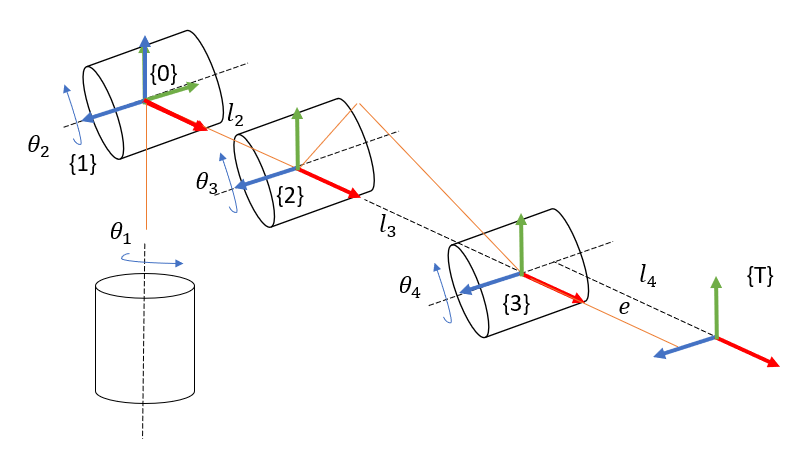

Definiendo de esta forma la tabla de parámetros DHstd

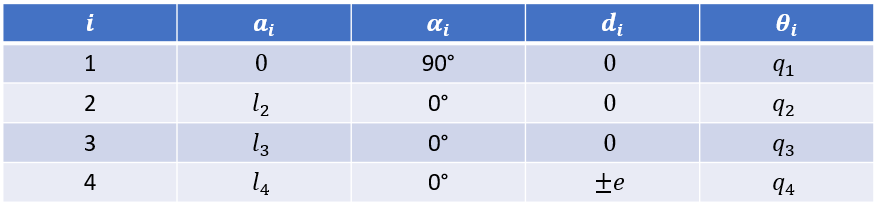

Con estos parámetros, se construyen las matrices de transformación homogéneas que relacionan a los eslabones sucesivos.

syms q1 q2 q3 q4 l2 l3 l4 e
T10 = MTH(q1,0,0,90,2)

$$T10 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T21 = MTH(q2,0,l2,0,2)

$$T21 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & l_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T32 = MTH(q3,0,l3,0,2)

$$T32 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & l_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & l_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TT3 = MTH(q4,e,l4,0,2)

$$TT3 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & l_{4}\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & l_{4}\,\sin\left(q_{4}\right)\\ 0 & 0 & 1 & e\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Se obtiene la cinemática directa del manipulador

T20 = T10*T21*T32*TT3

$$T20 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Finalmente, se obtiene la visualización con el toolbox de Peter Corke

%Se asignan las longitudes de los eslabones
l2 = 10;
l3 = 15;
l4 = 10;
e = 2;

%Se crea la matriz de parámetros 
L(1) = Revolute('d',0,'a',0,'alpha',pi/2);
L(2) = Revolute('d',0,'a',l2,'alpha',0);
L(3) = Revolute('d',0,'a',l3,'alpha',0);
L(4) = Revolute('d',e,'a',l4,'alpha',0);

%Se instancia el robot
r = SerialLink(L)

 
r = 
 
noname (4 axis, RRRR, stdDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|      1.571|          0|
|  2|         q2|          0|         10|          0|          0|
|  3|         q3|          0|         15|          0|          0|
|  4|         q4|          2|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 

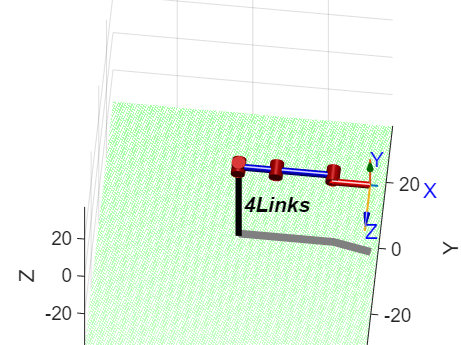

r.name = '4Links';

%Graficamos el robot
figure()
r.plot([0 0 0 0])
view([5.8 60.6])

function [H] = MTH(thetai,di,ai,alphai,angleType)
%Hecho por Andrés Felipe Forero Salas
%Función para calcular la Matriz de Transformación Homogénea
%dados los parámetros DHstd en diferentes posibles sistemas
%numéricos
    if angleType == 0 %rad
        H = [cos(thetai) -sin(thetai)*cos(alphai) sin(thetai)*sin(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cos(alphai) -cos(thetai)*sin(alphai) ai*sin(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    elseif angleType == 1 %degrees
        H = [cosd(thetai) -sind(thetai)*cosd(alphai) sind(thetai)*sind(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cosd(alphai) -cosd(thetai)*sind(alphai) ai*sind(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 2 %thetai en rad, alphai en degree
        H = [cos(thetai) -sin(thetai)*cosd(alphai) sin(thetai)*sind(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cosd(alphai) -cos(thetai)*sind(alphai) ai*sin(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 3 %thetai en degree, alphai en rad
        H = [cosd(thetai) -sind(thetai)*cos(alphai) sind(thetai)*sin(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cos(alphai) -cosd(thetai)*sin(alphai) ai*sind(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    end
end